# DMRG: Single-site update for excited state search

Author: [Seung-Sup Lee](https://cqm.snu.ac.kr)

In this tutorial, we will obtain the first excited state of the XY spin chain, which we studied in the previous tutorial. Again, we focus on the case of even length $L$ of the chain. In such case, the first-excited-state energy is analytically given by 


$$E_1 = E_{0} + \sin \frac{\pi}{2(L+1)},$$


where $E_0$ is the ground-state energy.

We repeat the preparation for the DMRG calculations, as done in the previous material. We first set system and numerical parameters, and define local operators and the MPO Hamiltonian.

clear

% system parameter
J = -1; % coupling strength
L = 40; % number of sites in a chain

% DMRG parameter
Nkeep = 30; % bond dimension
Nsweep = 4; % number of pairs of left+right sweeps

% Local operators
[S,I] = getLocalSpace('Spin',1/2);

% % MPO formulation of Hamiltonian
% Hamiltonian tensor for each chain site
Hloc = cell(4,4);
Hloc(:) = {zeros(size(I))};
Hloc{1,1} = I;
Hloc{2,1} = S(:,:,1);
Hloc{3,1} = S(:,:,3);
Hloc{4,2} = J*S(:,:,1)';
Hloc{4,3} = J*S(:,:,3)';
Hloc{end,end} = I;
Hloc = cell2mat(reshape(Hloc,[1 1 size(Hloc,1) size(Hloc,2)]));

% full chain
Hs = cell(1,L);
Hs(:) = {Hloc};
Hs{1} = Hs{1}(:,:,end,:); % choose the last components of the left leg
Hs{end} = Hs{end}(:,:,:,1); % choose the first components of the right leg

We use the ground (first excited) state from iterative diagonalization as the initial guess for the variational search of the ground (first excited) state. Note that, in iterative diagonalization, the MPS representations of both the ground and first excited states are equal except for the last tensor.

M0init = cell(1,L); % for the ground state
M1init = cell(1,L); % for the first excited state

% tensors for the vaccum (i.e., dummy leg)
Hprev = 1; % initialize Hamiltonian with 1, as we will use MPO
Aprev = 1; % identity tensor for the dummy leg

for itN = (1:L)
    % add new site
    Anow = getIdentity(Aprev,2,I,2,[1 3 2]);
    Hnow = updateLeft(Hprev,3,Anow,Hs{itN},4,Anow);

    Hmat = Hnow(:,:,1);
    [V,D] = eig((Hmat+Hmat')/2);
    [D,ids] = sort(diag(D),'ascend');
    if itN < L
        Ntr = min([numel(D);Nkeep]);
    else
        Ntr = 1;

        % obtain the last tensor for the first excited state
        M1init{itN} = contract(Anow,3,2,V(:,ids(Ntr+1)),2,1,[1 3 2]);
    end
    V = V(:,ids(1:Ntr));
    M0init{itN} = contract(Anow,3,2,V,2,1,[1 3 2]);
    
    Hprev = contract(Hnow,3,2,V,2,1);
    Hprev = contract(V',2,2,Hprev,3,1,[1 3 2]);
    Aprev = M0init{itN};
end

M1init(1:end-1) = M0init(1:end-1);

Compute the ground state with the single-site DMRG.

[M0,E0,E0iter] = DMRG_GS_1site(M0init,Hs,Nkeep,Nsweep);

22-09-27 09:35:21 | Single-site DMRG: ground state search
22-09-27 09:35:21 | # of sites = 40, Nkeep = 30, # of sweeps = 4 x 2
22-09-27 09:35:22 | Sweep #1/8 (right -> left) : Energy = -12.55385
22-09-27 09:35:22 | Sweep #2/8 (left -> right) : Energy = -12.5539
22-09-27 09:35:22 | Sweep #3/8 (right -> left) : Energy = -12.5539
22-09-27 09:35:22 | Sweep #4/8 (left -> right) : Energy = -12.5539
22-09-27 09:35:22 | Sweep #5/8 (right -> left) : Energy = -12.5539
22-09-27 09:35:22 | Sweep #6/8 (left -> right) : Energy = -12.5539
22-09-27 09:35:23 | Sweep #7/8 (right -> left) : Energy = -12.5539
22-09-27 09:35:23 | Sweep #8/8 (left -> right) : Energy = -12.5539
Elapsed time: 1.364s, CPU time: 15.54s, Avg # of cores: 11.39


E0_exact = 0.5 - (1/2/sin(pi/2/(L+1))); % exact value
disptime(['Exact GS energy = ',sprintf('%.5g',E0_exact),', DMRG = ', ...
    sprintf('%.5g',E0),', error = ',sprintf('%.5g',E0-E0_exact)]);

22-09-27 09:35:23 | Exact GS energy = -12.554, DMRG = -12.554, error = 9.6503e-07


## Exercise (a): Complete the single-site DMRG for first excited state search

There is a function `DMRG_1ES_1site_Ex.m`, which is in the same sub-directory with this script. It is incomplete. Complete the parts enclosed by the comments `TODO (start)` and `TODO (end)`. This exercise can be solved by making small changes to the ground state search function, `DMRG_GS_1site.m`.

Once you complete Exercise (a), then the completed function will run like:

[M1,E1,E1iter] = DMRG_1ES_1site_Ex(M1init,M0,Hs,Nkeep,Nsweep);

22-09-27 09:35:23 | Single-site DMRG: first excited state search
22-09-27 09:35:23 | # of sites = 40, Nkeep = 30, # of sweeps = 4 x 2
22-09-27 09:35:23 | Sweep #1/8 (right -> left) : Energy = -12.51542
22-09-27 09:35:23 | Sweep #2/8 (left -> right) : Energy = -12.51559
22-09-27 09:35:23 | Sweep #3/8 (right -> left) : Energy = -12.51559
22-09-27 09:35:24 | Sweep #4/8 (left -> right) : Energy = -12.51559
22-09-27 09:35:24 | Sweep #5/8 (right -> left) : Energy = -12.51559
22-09-27 09:35:24 | Sweep #6/8 (left -> right) : Energy = -12.51559
22-09-27 09:35:24 | Sweep #7/8 (right -> left) : Energy = -12.51559
22-09-27 09:35:24 | Sweep #8/8 (left -> right) : Energy = -12.51559
Elapsed time: 1.686s, CPU time: 18.93s, Avg # of cores: 11.23


You can verify your implementation by checking whether the first-excited-state energy is


$$E_{1} = \frac{1}{2} - \frac{1}{2\sin \frac{\pi}{2(N+1)}} + \sin \frac{\pi}{2(L+1)}.$$


E1_exact = 0.5 - (1/2/sin(pi/2/(L+1))) + sin(pi/2/(L+1));
disptime(['Exact 1st-excited-state energy = ',sprintf('%.5g',E1_exact), ...
    ', DMRG = ',sprintf('%.5g',E1),', error = ', ...

22-09-27 09:35:24 | Exact 1st-excited-state energy = -12.516, DMRG = -12.516, error = 3.1896e-06


    sprintf('%.5g',E1-E1_exact)]);

Also we see how the variational energy converges to the exact value. The error is $O(10^{-6})$, similarly as for the error for the ground state. These errors can be further decreased by using larger bond dimension `Nkeep`.

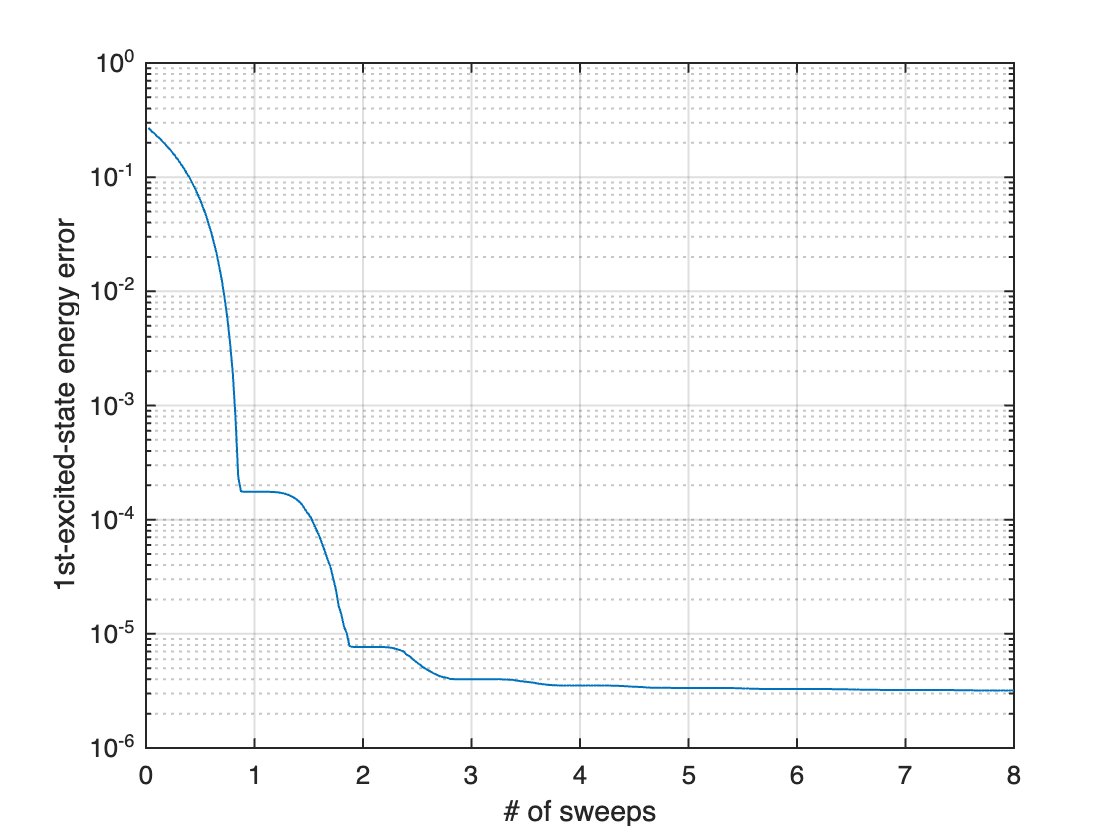

figure;
semilogy((1:numel(E1iter))/L,E1iter(:)-E1_exact,'LineWidth',1);
set(gca,'FontSize',13,'LineWidth',1);
xlim([0 2*Nsweep]);
grid on;
xlabel('# of sweeps');
ylabel('1st-excited-state energy error');

We can also compute the spin-spin correlation function $\langle \Psi_1 |\hat{S}_{\ell,+} \hat{S}_{\ell+1,-} | \Psi_1 \rangle$ with respect to the first excited state $|\Psi_1\rangle$ and compare it with that for the ground state.

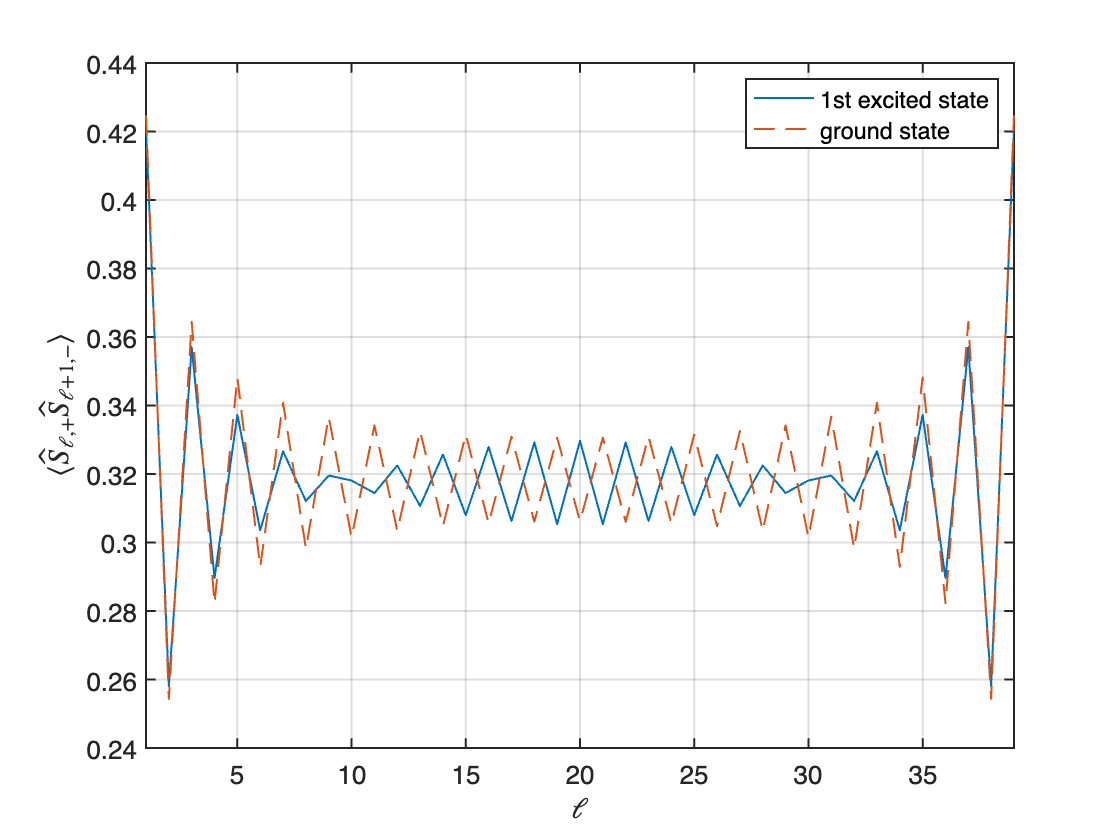

% compute correlation function for the nearest-neighbour spins
SS = zeros(1,L-1);
for itN = (2:L)
    T = updateLeft([],[],M1{itN-1},S(:,:,1)*sqrt(2),3,M1{itN-1});
    T = updateLeft(T,3,M1{itN},S(:,:,3)*sqrt(2),3,M1{itN});
    
    for itN2 = ((itN+1):L)
        T = updateLeft(T,2,M1{itN2},[],[],M1{itN2});
    end
    
    SS(itN-1) = T;
end

% exact relation for the ground state
SS_exact = (((-1).^(1:L-1))./sin((2*(1:L-1)+1)*pi/2/(L+1)) - ...
    1./sin(pi/2/(L+1)))/(-2*(L+1));

figure;
plot((1:L-1),SS,'-',(1:L-1),SS_exact,'--','LineWidth',1);
legend({'1st excited state','ground state'});
set(gca,'FontSize',13,'LineWidth',1);
xlabel('$\ell$','Interpreter','latex');
ylabel('$\langle \hat{S}_{\ell,+} \hat{S}_{\ell+1,-} \rangle$', ...
    'Interpreter','latex');
xlim([1 L-1]);
grid on;

We see that the correlation functions of the ground and first excited states are similar near the edges, while become out-of-phase near the center.